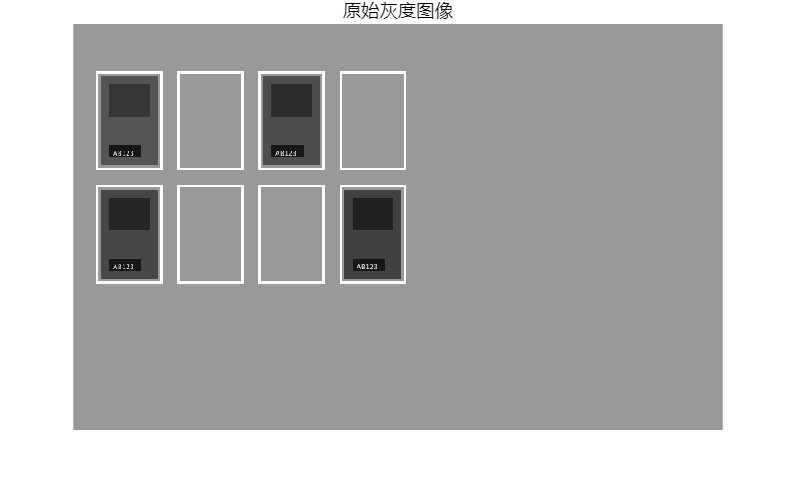

%%停车位占用检测与车牌区域增强系统
% 使用 MATLAB 内置 ocr 函数，需要 Computer Vision Toolbox
clear; clc; close all;

%%用户设置
useSimulated = true;
enableChinese = false;

%% 1. 获取图像
if useSimulated
    img = generateSimulatedParking();
else
    [filename, pathname] = uigetfile({'*.jpg;*.png;*.bmp','Image Files'}, '选择停车位图像');
    if isequal(filename,0), error('未选择图像文件'); end
    img = imread(fullfile(pathname, filename));
end

if size(img,3)==3, grayImg = rgb2gray(img); else, grayImg = img; end
grayImg = im2double(grayImg);

figure('Name','原始图像','NumberTitle','off');
imshow(grayImg); title('原始灰度图像');

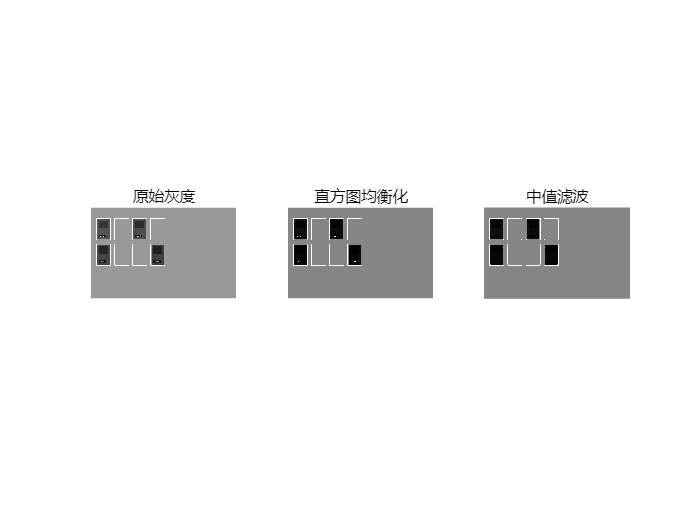


%% 2. 停车位区域定义（右键继续，回车结束）
if useSimulated
    parkingROIs = {
        [30, 60, 80, 120]; [130, 60, 80, 120]; [230, 60, 80, 120]; [330, 60, 80, 120];
        [30, 200, 80, 120]; [130, 200, 80, 120]; [230, 200, 80, 120]; [330, 200, 80, 120];
    };
    numSpaces = length(parkingROIs);
else
    fig = figure('Name','框选停车位','NumberTitle','off');
    imshow(img); title('左键框选，右键继续，回车结束');
    parkingROIs = {}; set(fig, 'CurrentCharacter', char(0));
    while true
        h = drawrectangle('Label','框选车位','Color','r');
        if isempty(h) || ~isvalid(h), break; end
        pos = round(h.Position); parkingROIs{end+1} = pos; %#ok<AGROW>
        rectangle('Position', pos, 'EdgeColor','g','LineWidth',2);
        set(fig, 'CurrentCharacter', char(0)); drawnow; title('右键继续，回车结束');
        validAction = false;
        while ~validAction
            w = waitforbuttonpress;
            if w == 0
                if strcmp(get(fig,'SelectionType'), 'alt'), validAction = true; end
            else
                if double(get(fig,'CurrentCharacter')) == 13, validAction = true; break; end
            end
        end
        if w ~= 0 && double(get(fig,'CurrentCharacter')) == 13, break; end
    end
    close(fig); numSpaces = length(parkingROIs);
    if numSpaces == 0, error('未选择任何停车位区域'); end
end

%% 3. 预处理
eqImg = histeq(grayImg); medImg = medfilt2(eqImg, [5 5]);
figure('Name','预处理结果','NumberTitle','off');
subplot(1,3,1); imshow(grayImg); title('原始灰度');
subplot(1,3,2); imshow(eqImg); title('直方图均衡化');
subplot(1,3,3); imshow(medImg); title('中值滤波');

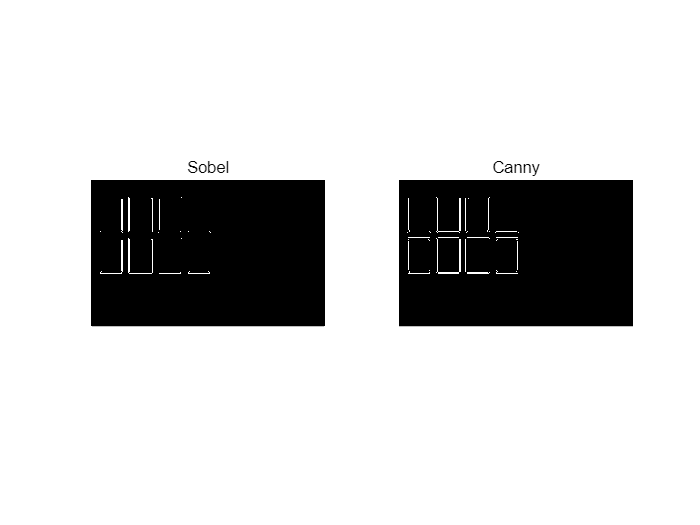


%% 4. 边缘检测
sobelEdges = edge(medImg, 'sobel'); cannyEdges = edge(medImg, 'canny', [0.1 0.3]);
figure('Name','边缘检测比较','NumberTitle','off');
subplot(1,2,1); imshow(sobelEdges); title('Sobel');
subplot(1,2,2); imshow(cannyEdges); title('Canny');

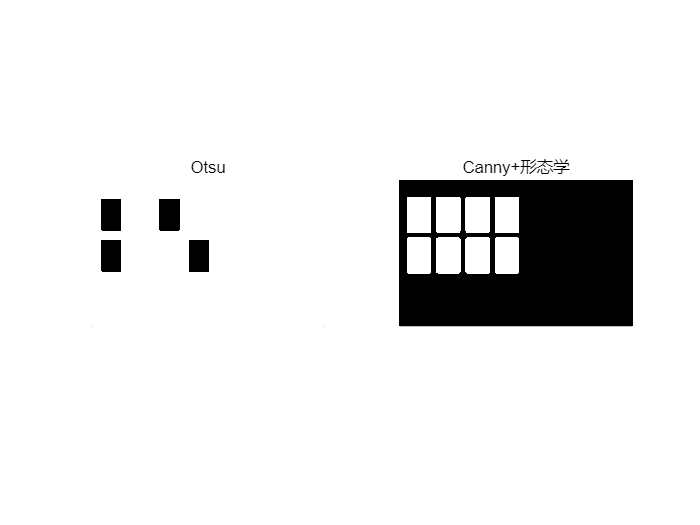


%% 5. 分割
level = graythresh(medImg); bwOtsu = imbinarize(medImg, level);
se = strel('disk', 3);
bwEdgeFilled = imdilate(cannyEdges, se); bwEdgeFilled = imfill(bwEdgeFilled, 'holes');
bwEdgeFilled = imerode(bwEdgeFilled, se);
figure('Name','分割比较','NumberTitle','off');
subplot(1,2,1); imshow(bwOtsu); title('Otsu');
subplot(1,2,2); imshow(bwEdgeFilled); title('Canny+形态学');

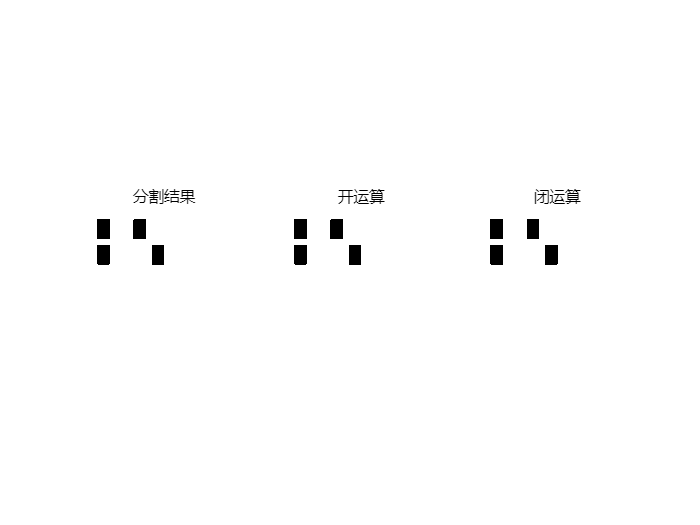

bwSelected = bwOtsu;

%% 6. 形态学
se2 = strel('disk', 5);
bwOpen = imopen(bwSelected, se2); bwClose = imclose(bwOpen, se2);
figure('Name','形态学处理','NumberTitle','off');
subplot(1,3,1); imshow(bwSelected); title('分割结果');
subplot(1,3,2); imshow(bwOpen); title('开运算');
subplot(1,3,3); imshow(bwClose); title('闭运算');

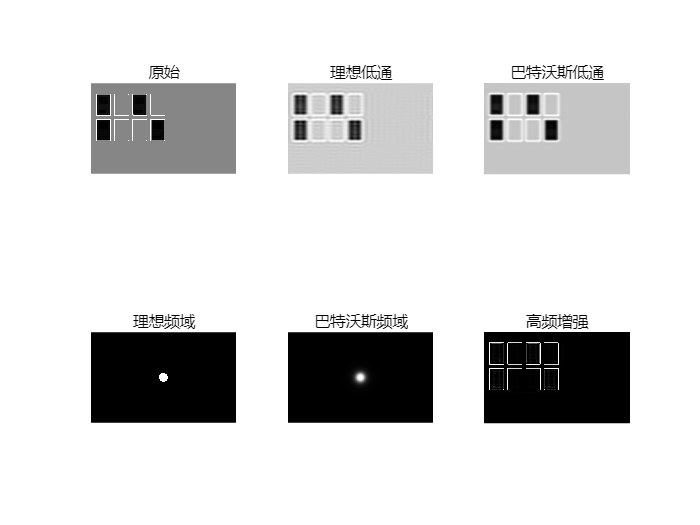

bwFinal = bwClose;

%% 7. 频域处理
[M,N]=size(medImg); F=fftshift(fft2(medImg)); D0=0.05; n_bw=2;
u=(1:M)-floor(M/2); v=(1:N)-floor(N/2); [V,U]=meshgrid(v,u); D=sqrt(U.^2+V.^2);
H_ideal=double(D<=D0*min(M,N)); H_butter=1./(1+(D./(D0*min(M,N))).^(2*n_bw));
img_ideal_low=real(ifft2(ifftshift(F.*H_ideal))); img_butter_low=real(ifft2(ifftshift(F.*H_butter)));
img_high_enhanced=medImg-img_butter_low; img_high_enhanced=imadjust(img_high_enhanced);
figure('Name','频域处理','NumberTitle','off');
subplot(2,3,1); imshow(medImg); title('原始');
subplot(2,3,2); imshow(img_ideal_low,[]); title('理想低通');
subplot(2,3,3); imshow(img_butter_low,[]); title('巴特沃斯低通');
subplot(2,3,4); imshow(H_ideal,[]); title('理想频域');
subplot(2,3,5); imshow(H_butter,[]); title('巴特沃斯频域');
subplot(2,3,6); imshow(img_high_enhanced,[]); title('高频增强');


%% 8. 占用检测（多特征综合得分）
border = 6;
occupiedFlags = false(numSpaces, 1);
meanVals = zeros(numSpaces, 1); varVals = zeros(numSpaces, 1); edgeVals = zeros(numSpaces, 1);
for i = 1:numSpaces
    roi = parkingROIs{i};
    x = roi(1); y = roi(2); w = roi(3); h = roi(4);
    x_in = x + border; y_in = y + border;
    w_in = w - 2*border; h_in = h - 2*border;
    if w_in <= 0 || h_in <= 0, x_in = x; y_in = y; w_in = w; h_in = h; end
    roiGray = imcrop(medImg, [x_in, y_in, w_in, h_in]);
    meanVals(i) = mean(roiGray(:));
    varVals(i)  = var(roiGray(:));
    edgesROI = edge(roiGray, 'canny', [0.1 0.3]);
    edgeVals(i) = sum(edgesROI(:)) / numel(edgesROI);
end
medMean = median(meanVals); medVar = median(varVals); medEdge = median(edgeVals);
scores = zeros(numSpaces, 1);
for i = 1:numSpaces
    darkScore = (medMean - meanVals(i)) / medMean;
    edgeScore = (edgeVals(i) - medEdge) / medEdge;
    varScore  = (varVals(i) - medVar) / medVar;
    scores(i) = darkScore + edgeScore + varScore;
end
threshold = 0.0;
fprintf('\n========== 车位特征与得分 ==========\n');


========== 车位特征与得分 ==========


for i = 1:numSpaces
    isOccupied = (scores(i) > threshold);
    occupiedFlags(i) = isOccupied;
    fprintf('车位%d: 得分=%.3f -> %s\n', i, scores(i), string(isOccupied));
end

车位1: 得分=2.582 -> true
车位2: 得分=-0.839 -> false
车位3: 得分=1.131 -> true
车位4: 得分=-0.839 -> false
车位5: 得分=0.927 -> true
车位6: 得分=-0.839 -> false
车位7: 得分=-0.839 -> false
车位8: 得分=0.927 -> true


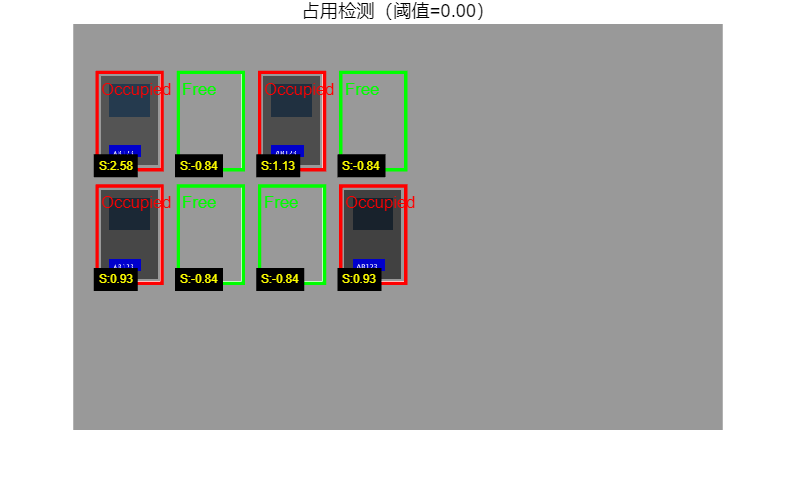

figure('Name','占用检测结果','NumberTitle','off');
imshow(img); hold on;
for i = 1:numSpaces
    roi = parkingROIs{i};
    x = roi(1); y = roi(2); w = roi(3); h = roi(4);
    if occupiedFlags(i)
        rectangle('Position', [x, y, w, h], 'EdgeColor', 'r', 'LineWidth', 2);
        text(x+5, y+20, 'Occupied', 'Color', 'red', 'FontSize', 10);
    else
        rectangle('Position', [x, y, w, h], 'EdgeColor', 'g', 'LineWidth', 2);
        text(x+5, y+20, 'Free', 'Color', 'green', 'FontSize', 10);
    end
    text(x+2, y+h-5, sprintf('S:%.2f', scores(i)), 'Color','yellow','FontSize',7,'BackgroundColor','k');
end
title(sprintf('占用检测（阈值=%.2f）', threshold));
hold off;

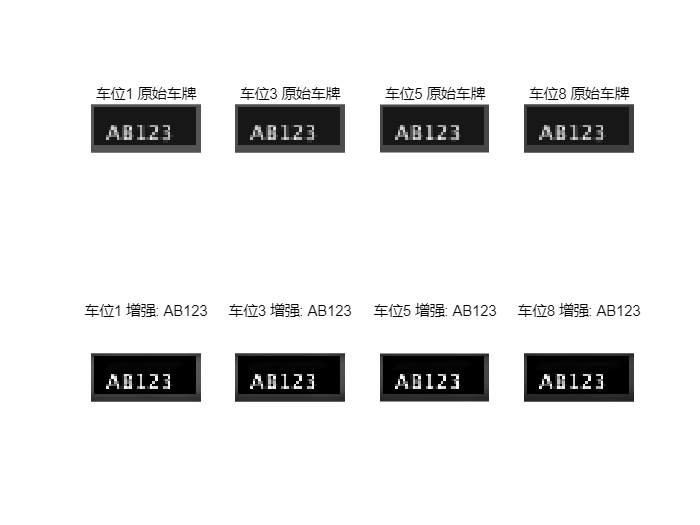

车位1: 识别结果 = AB123


车位3: 识别结果 = AB123


车位5: 识别结果 = AB123


车位8: 识别结果 = AB123





%% 9. 车牌区域增强与OCR识别（使用内置ocr）
numOcc = sum(occupiedFlags);
figure('Name','车牌增强与识别','NumberTitle','off');
if numOcc == 0
    text(0.5,0.5,'未检测到清晰车牌区域','Units','normalized','HorizontalAlignment','center');
else
    plateCount = 0;
    for i = 1:numSpaces
        if ~occupiedFlags(i), continue; end
        roi = parkingROIs{i};
        x = roi(1); y = roi(2); w = roi(3); h = roi(4);
        vehiclePatch = imcrop(img, [x, y, w, h]);
        
        plateROI = locatePlateCandidate(vehiclePatch);
        if isempty(plateROI), continue; end
        
        plateCount = plateCount + 1;
        px = plateROI(1); py = plateROI(2); pw = plateROI(3); ph = plateROI(4);
        plateImgColor = imcrop(vehiclePatch, [px, py, pw, ph]);  % 彩色车牌
        
        % 频域增强显示
        plateGrayDisp = rgb2gray(plateImgColor);
        plateGrayDisp = im2double(plateGrayDisp);
        [m,n] = size(plateGrayDisp);
        Fp = fftshift(fft2(plateGrayDisp));
        [Vp,Up] = meshgrid((1:n)-floor(n/2), (1:m)-floor(m/2));
        Dp = sqrt(Up.^2 + Vp.^2);
        D0p = 0.1 * min(m,n);
        Hp = 1 ./ (1 + (Dp./D0p).^(2*2));
        plateLow = real(ifft2(ifftshift(Fp .* Hp)));
        plateEnhanced = plateGrayDisp - plateLow;
        plateEnhanced = imadjust(plateEnhanced);
        
        % 使用内置OCR，适当放大图像提高识别率
        plateStr = recognizePlate_OCR(plateImgColor);
        fprintf('车位%d: 识别结果 = %s\n', i, plateStr);
        
        subplot(2, numOcc, plateCount);
        imshow(plateGrayDisp); title(sprintf('车位%d 原始车牌', i));
        subplot(2, numOcc, plateCount + numOcc);
        imshow(plateEnhanced); title(sprintf('车位%d 增强: %s', i, plateStr));
    end
end


%%辅助函数

function img = generateSimulatedParking()
    img = 0.6 * ones(500, 800, 3);
    img = insertShape(img, 'Rectangle', [30,60,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [130,60,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [230,60,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [330,60,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [30,200,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [130,200,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [230,200,80,120], 'Color','white','LineWidth',3);
    img = insertShape(img, 'Rectangle', [330,200,80,120], 'Color','white','LineWidth',3);
    rng(42); occupied = [1,3,5,8];
    positions = {[30,60],[130,60],[230,60],[330,60],[30,200],[130,200],[230,200],[330,200]};
    for idx = occupied
        pos = positions{idx}; x=pos(1); y=pos(2);
        img = insertShape(img, 'FilledRectangle', [x+5,y+5,70,110], 'Color',[0.3 0.3 0.3],'Opacity',0.9);
        img = insertShape(img, 'FilledRectangle', [x+15,y+15,50,40], 'Color',[0.1 0.2 0.3],'Opacity',0.8);
        img = insertShape(img, 'FilledRectangle', [x+15,y+90,40,15], 'Color',[0 0 0.8],'Opacity',1);
        img = insertText(img, [x+17,y+92], 'AB123', 'FontSize',8, ...
            'BoxOpacity',0, 'TextColor','white');
    end
    img = im2double(img);
end

function plateROI = locatePlateCandidate(vehiclePatch)
    if size(vehiclePatch,3)==3, gray=rgb2gray(vehiclePatch); else, gray=vehiclePatch; end
    gray=im2double(gray); edges=edge(gray,'canny',[0.1 0.3]);
    [h,w]=size(edges); bottom=round(h*0.33):h;
    edgesBottom=false(size(edges)); edgesBottom(bottom,:)=edges(bottom,:);
    se=strel('rectangle',[3,8]); edgesClose=imclose(edgesBottom,se);
    stats=regionprops(edgesClose,'BoundingBox','Area');
    bestScore=0; plateROI=[];
    for k=1:length(stats)
        bbox=stats(k).BoundingBox; aspect=bbox(3)/bbox(4);
        if aspect>1.5 && aspect<6 && bbox(3)>=10 && bbox(4)>=5
            plateRegion=imcrop(edges,bbox); density=sum(plateRegion(:))/numel(plateRegion);
            score=density*stats(k).Area;
            if score>bestScore, bestScore=score; plateROI=bbox; end
        end
    end
end

function plateStr = recognizePlate_OCR(plateImgColor)
    % 使用内置OCR识别车牌字符
    % 输入：彩色车牌图像（double 0-1）
    if ~isa(plateImgColor, 'uint8')
        plateImgColor = im2uint8(plateImgColor);
    end
    % 放大4倍提高识别率
    plateImgLarge = imresize(plateImgColor, 4, 'bicubic');
    % 灰度化
    grayLarge = rgb2gray(plateImgLarge);
    % 增强对比度
    grayLarge = imadjust(grayLarge);
    % 大津二值化
    bw = imbinarize(grayLarge, 'adaptive', 'ForegroundPolarity', 'bright', 'Sensitivity', 0.4);
    % 反转
    bw = ~bw;
    % 调用OCR函数，设置字符集为数字和大写字母，限制感兴趣区域
    results = ocr(bw, 'CharacterSet', '0123456789ABCDEFGHIJKLMNOPQRSTUVWXYZ');
    plateStr = results.Text;
    % 去除空格和无效字符
    plateStr = strrep(plateStr, ' ', '');
    if isempty(plateStr)
        % 若失败，直接OCR原灰度放大图
        results = ocr(grayLarge, 'CharacterSet', '0123456789ABCDEFGHIJKLMNOPQRSTUVWXYZ');
        plateStr = strrep(results.Text, ' ', '');
    end
end